**Import data**

data = readmatrix('All data merged ready for training.csv')

data =    50.0000         0    0.1000    0.2000    0.2000    2.2891    0.1402    4.9081    0.2372    2.2656    0.1396    2.9920    0.2314    1.6920    1.0104
   50.0000         0    0.5950    0.2000    0.2000    2.3871    0.1320    4.8579    0.2366    2.3789    0.1306    2.9448    0.2309    1.7028    1.0035
   50.0000         0    1.0900    0.2000    0.2000    2.4783    0.1259    4.8106    0.2361    2.4798    0.1245    2.8995    0.2304    1.7139    0.9994
   50.0000         0    1.5850    0.2000    0.2000    2.5612    0.1215    4.7649    0.2357    2.5684    0.1204    2.8549    0.2300    1.7255    0.9972
   50.0000         0    2.0800    0.2000    0.2000    2.6359    0.1182    4.7200    0.2352    2.6460    0.1177    2.8102    0.2296    1.7378    0.9962
   50.0000         0    2.5750    0.2000    0.2000    2.7031    0.1159    4.6754    0.2348    2.7144    0.1158    2.7653    0.2292    1.7509    0.9958
   50.0000         0    3.0700    0.2000    0.2000    2.7634    0.1143    4.6307    0.2

x=data(:,1:5);
y=data(:,14:15);

**Visualization of the data**

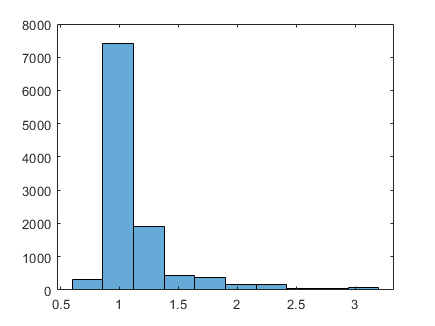

histogram(y(:,1),10);

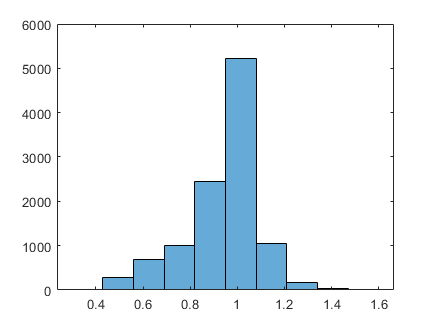

histogram(y(:,2),10);

**Normalize Features (using log normalization in output)**

Varience=var(data(:,14:15))

Varience =     0.1167    0.0229


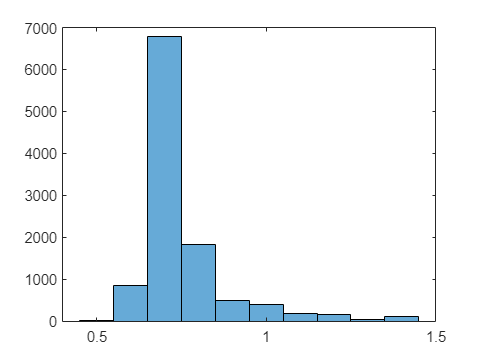

[x2_log,y2_log]=normalize(x,y);
histogram(y2_log(:,1),10)

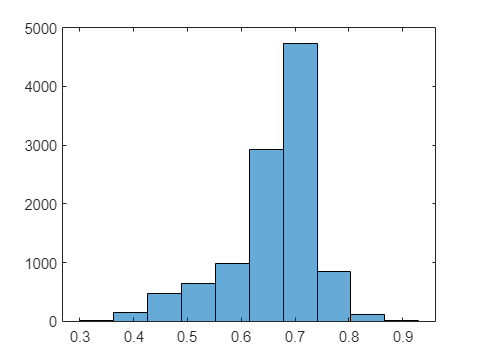

histogram(y2_log(:,2),10)

**Normalize Feature (using standard normalization in output)**

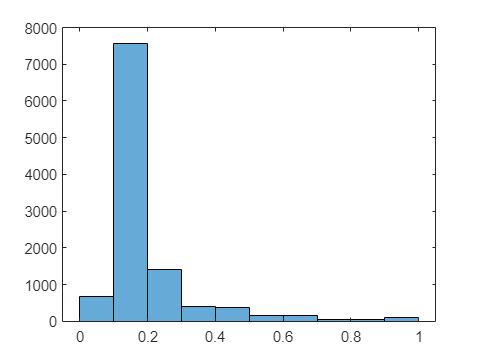

[x2,y2]=normalize_std(x,y);
histogram(y2(:,1),10)

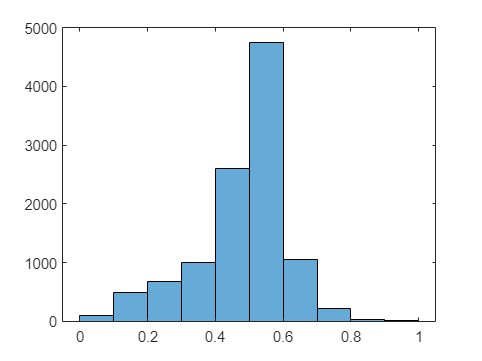

histogram(y2(:,2),10)

**Train an artificial neural network (ANN)**

 
Computing Resources:
MEX on PCWIN64
 


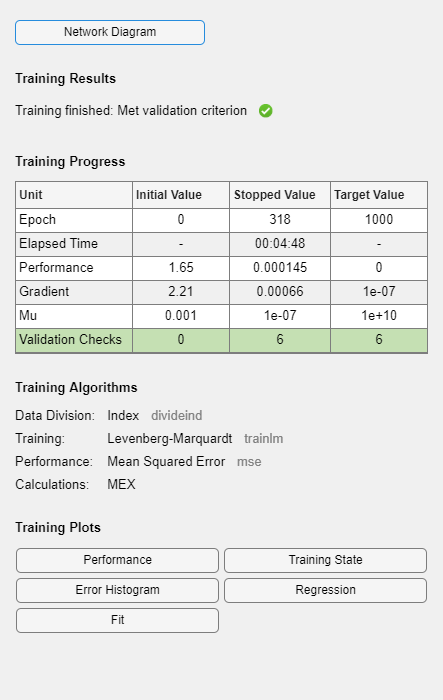

xt=x2';
yt=y2';
hiddenLayerSize=50;
lm=fitnet(hiddenLayerSize,"trainlm");
lm.divideFcn="divideind";
lm.divideParam.trainInd=Training_index';
lm.divideParam.valInd=Validation_index';
lm.divideParam.testInd=[];
[lm,tr_lm]=train(lm,xt,yt,'showresources','yes');

**Performence of the model**

Training set

Y=lm(xt(:,tr_lm.trainInd));
Yt=yt(:,tr_lm.trainInd);
yTrain_lm=(Y'.*(max(y)-min(y))+min(y))';
yTrainTrue_lm=(Yt'.*(max(y)-min(y))+min(y))';
perf_P_lm=rMetrics(yTrainTrue_lm(1,:),yTrain_lm(1,:));
perf_Nu_lm=rMetrics(yTrainTrue_lm(2,:),yTrain_lm(2,:));
row_names_lm=array2table({'Pressure_ratio';'Nusselt ratio'});
T_lm_train=cat(1,perf_P_lm,perf_Nu_lm);
T_lm_train=cat(2,row_names_lm,T_lm_train)

T_lm_train = 2×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.017026    0.00055922    0.023648    0.99499    1.4926
    {'Nusselt ratio' }    0.010995    0.00026196    0.016185    0.98855    1.3067


Validation set

Y_val=lm(xt(:,tr_lm.valInd));
Yt_val=yt(:,tr_lm.valInd);
yVal_lm=(Y_val'.*(max(y)-min(y))+min(y))';
yValTrue_lm=(Yt_val'.*(max(y)-min(y))+min(y))';
perf_P_lm=rMetrics(yValTrue_lm(1,:),yVal_lm(1,:));
perf_Nu_lm=rMetrics(yValTrue_lm(2,:),yVal_lm(2,:));
T_lm_val=cat(1,perf_P_lm,perf_Nu_lm);
T_lm_val=cat(2,row_names_lm,T_lm_val)

T_lm_val = 2×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.017061    0.00055604    0.023581    0.99578    1.5038
    {'Nusselt ratio' }    0.011619    0.00030845    0.017563    0.98653    1.3942


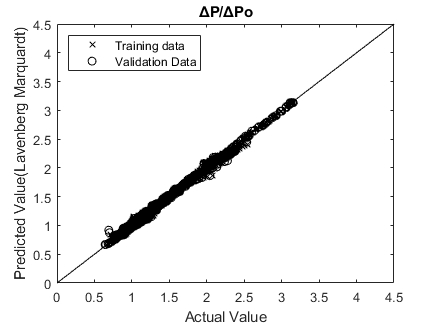

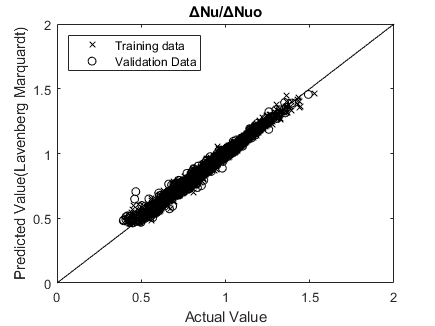

for i=1:2
    figure()
    plot(yTrainTrue_lm(i,:),yTrain_lm(i,:),'x','color','k');hold on;
    plot(0:5,0:5,'color','k');
    plot(yValTrue_lm(i,:),yVal_lm(i,:),'o','color','k');
    if i==1
        xlim([0 4.5])
        ylim([0 4.5])
    else
        xlim([0 2])
        ylim([0 2])
    end
    legend('Training data','','Validation Data','location','northwest')
    ylabel('Predicted Value(Lavenberg Marquardt)')
    xlabel('Actual Value')
    if i==1
        title('ΔP/ΔPo');
    else
        title('ΔNu/ΔNuo');
    end
    hold off;
    if i==1
        Plot_LM_1=sprintf('D:/Matlab Drive/Research/Figure/LM/ΔP÷ΔPo.bmp');
        saveas(gcf,Plot_LM_1)
    else
        Plot_LM_1=sprintf('D:/Matlab Drive/Research/Figure/LM/ΔNu÷ΔNuo.bmp');
        saveas(gcf,Plot_LM_1)
    end
end

**Optimization**

%run to clear previous variable value
clear("rms_train_lm",'rms_val_lm','r2_train_lm',"r2_val_lm",'mape_train_lm',"mape_val_lm",'name')

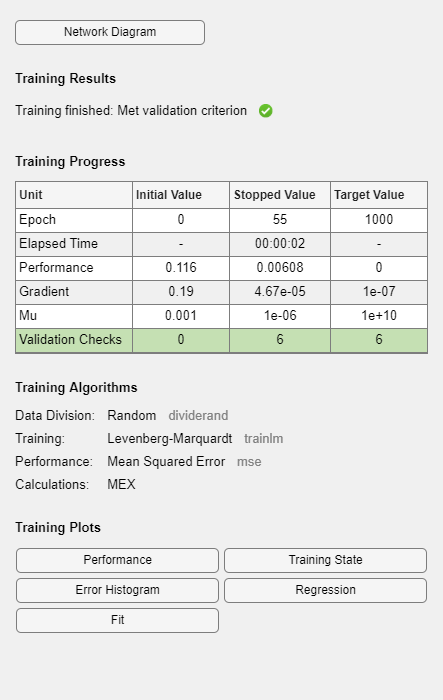


%select all and press ctrl+T to enable section
hiddenLayerNo=[1,2,3];
for i=1:50
    %defining the architecture of the Ann
    hiddenLayerSize=i;
    lm=fitnet(hiddenLayerSize,'trainlm');
    lm.divideFcn = 'divideind';
    lm.divideParam.trainInd = tr_lm.trainInd;
    lm.divideParam.valInd = tr_lm.valInd;
    lm.divideParam.testInd= tr_lm.testInd;
     %training of Ann
    [lm,tr_lm]=train(lm,xt,yt);
    Y_lm=lm(xt(:,tr_lm.trainInd));
    Yt_lm=yt(:,tr_lm.trainInd);
    Yv_lm=lm(xt(:,tr_lm.valInd));
    Yvt_lm=yt(:,tr_lm.valInd);

    yTrain_lm=(Y_lm'.*(max(y)-min(y))+min(y))';
    yTrainTrue_lm=(Yt_lm'.*(max(y)-min(y))+min(y))';
    yVal_lm=(Yv_lm'.*(max(y)-min(y))+min(y))';
    yValTrue_lm=(Yvt_lm'.*(max(y)-min(y))+min(y))';
    %RMSE
    for j=1:2
        rms_train_lm(i,j)=sqrt(mean(((yTrain_lm(j,:)-yTrainTrue_lm(j,:)).^2),2));
    end   
    for j=1:2
        rms_val_lm(i,j)=sqrt(mean(((yVal_lm(j,:)-yValTrue_lm(j,:)).^2),2));
    end
    %R^2
    for j=1:2
        r2_train_lm(i,j)=1 - (sum(((yTrainTrue_lm(j,:) - yTrain_lm(j,:)).^2),2)/sum(((yTrainTrue_lm(j,:) - mean(yTrainTrue_lm(j,:),2)).^2),2));
    end   
    for j=1:2
        r2_val_lm(i,j)=1 - (sum(((yValTrue_lm(j,:) - yVal_lm(j,:)).^2),2)/sum(((yValTrue_lm(j,:) - mean(yValTrue_lm(j,:))).^2),2));
    end
    %MAPE
    for j=1:2
        mape_train_lm(i,j)=mean(abs((yTrainTrue_lm(j,:)-yTrain_lm(j,:))./yTrainTrue_lm(j,:)),2).*100;
    end   
    for j=1:2
        mape_val_lm(i,j)=mean(abs((yValTrue_lm(j,:)-yVal_lm(j,:))./yValTrue_lm(j,:)),2).*100;
    end
   name{i} = ['Hidden Layer size: ' num2str(i,'%d')];
   Ta_lm=array2table(rms_train_lm,"VariableNames",{'ΔP/ΔPo(rmse)','ΔNu/ΔNuo(rmse)'});
   Ta_lm.Properties.RowNames=name;
   Tb_lm=array2table(rms_val_lm,"VariableNames",{'ΔP/ΔPo(rmse)','ΔNu/ΔNuo(rmse)'});
   Tb_lm.Properties.RowNames=name;
end

%select all and press ctrl+T to enable section
Ta_lm

Ta_lm = 50×2 table
                             ΔP/ΔPo(rmse)    ΔNu/ΔNuo(rmse)
                             ____________    ______________

    Hidden Layer size: 1         0.2161          0.14912   
    Hidden Layer size: 2        0.15433          0.10951   
    Hidden Layer size: 3        0.15456          0.10559   
    Hidden Layer size: 4        0.09859          0.09675   
    Hidden Layer size: 5        0.11103         0.086317   
    Hidden Layer size: 6        0.08892         0.063282   
    Hidden Layer size: 7       0.090803         0.058255   
    Hidden Layer size: 8       0.082675         0.055175   
    Hidden Layer size: 9        0.08221         0.052425   
    Hidden Layer size: 10      0.075525         0.049685   
    Hidden Lay

Tb_lm

Tb_lm = 50×2 table
                             ΔP/ΔPo(rmse)    ΔNu/ΔNuo(rmse)
                             ____________    ______________

    Hidden Layer size: 1         0.2257          0.14985   
    Hidden Layer size: 2        0.15453          0.11277   
    Hidden Layer size: 3        0.15851          0.10449   
    Hidden Layer size: 4        0.10037         0.097603   
    Hidden Layer size: 5        0.10938         0.088137   
    Hidden Layer size: 6       0.091987         0.061888   
    Hidden Layer size: 7        0.08959         0.057295   
    Hidden Layer size: 8       0.085465         0.055683   
    Hidden Layer size: 9       0.078579         0.052338   
    Hidden Layer size: 10      0.078644         0.051059   
    Hidden Lay

r2_val_lm

r2_val_lm =     0.5375    0.0245
    0.7804    0.4635
    0.8033    0.5253
    0.9070    0.5891
    0.8991    0.6601
    0.9288    0.8331
    0.9323    0.8520
    0.9389    0.8598
    0.9454    0.8798
    0.9455    0.8866


writetable(Ta_lm,'D:/Matlab Drive/Research/Table/Performence_lm(training).xlsx','Sheet',1)
writetable(Tb_lm,'D:/Matlab Drive/Research/Table/Performence_lm(validation).xlsx','Sheet',1)

**Select Optimum no of neuron in hidden layer(RMSE)**

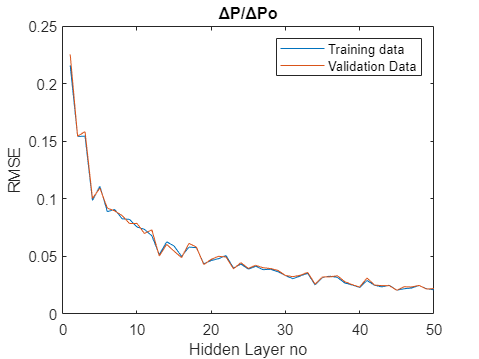

%select all and press ctrl+T to enable section
plot(1:i,rms_train_lm(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔP/ΔPo')
plot(1:i,rms_val_lm(:,1));
legend('Training data','Validation Data');hold off;
Plot_LM_2=sprintf('D:/Matlab Drive/Research/Figure/LM/ΔP÷ΔPo_optimisation(rmse).bmp');
saveas(gcf,Plot_LM_2)

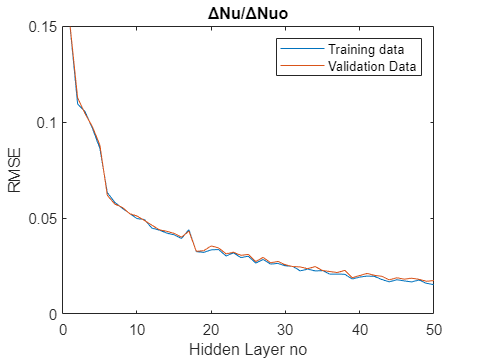

plot(1:i,rms_train_lm(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔNu/ΔNuo')
plot(1:i,rms_val_lm(:,2));
legend('Training data','Validation Data');hold off;
Plot_LM_2=sprintf('D:/Matlab Drive/Research/Figure/LM/ΔNu÷ΔNuo_optimisation(rmse).bmp');
saveas(gcf,Plot_LM_2)

**Select Optimum no of neuron in hidden layer(r2)**

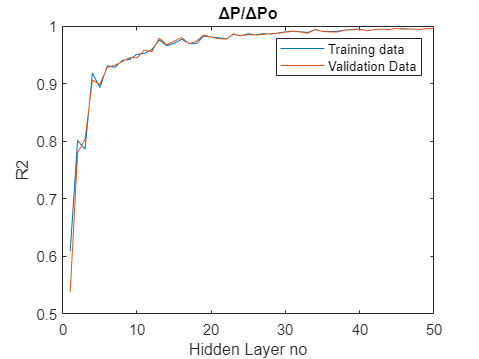

%select all and press ctrl+T to enable section
plot(1:i,r2_train_lm(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('R2')
title('ΔP/ΔPo')
plot(1:i,r2_val_lm(:,1));
legend('Training data','Validation Data');hold off;
Plot_LM_2=sprintf('D:/Matlab Drive/Research/Figure/LM/ΔP÷ΔPo_optimisation(r2).bmp');
saveas(gcf,Plot_LM_2)

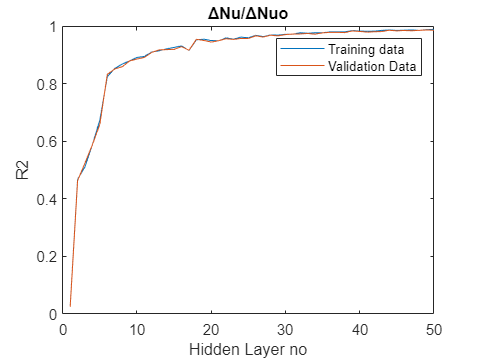

plot(1:i,r2_train_lm(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('R2')
title('ΔNu/ΔNuo')
plot(1:i,r2_val_lm(:,2));
legend('Training data','Validation Data');hold off;
Plot_LM_2=sprintf('D:/Matlab Drive/Research/Figure/LM/ΔNu÷ΔNuo_optimisation(r2).bmp');
saveas(gcf,Plot_LM_2)

**Select Optimum no of neuron in hidden layer(mape)**

%select all and press ctrl+T to enable section

i = 50

plot(1:i,mape_train_lm(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('mape')
title('ΔP/ΔPo')
plot(1:i,mape_val_lm(:,1));
legend('Training data','Validation Data');hold off;
Plot_LM_2=sprintf('D:/Matlab Drive/Research/Figure/LM/ΔP÷ΔPo_optimisation(mape).bmp');
saveas(gcf,Plot_LM_2)

plot(1:i,mape_train_lm(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('mape')
title('ΔNu/ΔNuo')
plot(1:i,mape_val_lm(:,2));
legend('Training data','Validation Data');hold off;
Plot_LM_2=sprintf('D:/Matlab Drive/Research/Figure/LM/ΔNu÷ΔNuo_optimisation(mape).bmp');
saveas(gcf,Plot_LM_2)

**Prediction**

X=[100,0,3.5650,0.2,0.2]

X =   100.0000         0    3.5650    0.2000    0.2000


for i=1:5
    Xt(:,i)=(X(:,i)-min(x(:,i)))/(max(x(:,i))-min(x(:,i)));
end
W=lm(Xt');
Y=exp(W(1,1))-1

Y = 0.4600

Z=exp(W(2,1))-1

Z = 0.6863